### **Communication Systems Laboratory**

**Lab 4: OFDM Transmission Using USRP**

**Students: **B11901006 臧逸新、B11901013 俞柏安、B11901101 謝函蓁

#### Wifi-Modulation Initialize



clc; clear; close all;
global pilot_idx;
global data_idx;
global N_FFT;
global N_CP;
global fs;
%% Parameters
N_FFT = 64;  % FFT size
N_CP = 16;   % Cyclic prefix length
N_OFDM = N_FFT+N_CP; 
fs = 10e6;   % Sampling rate (Hz)
ts = 1/fs;   % Sampling time
fc = 915e6;  % Carrier frequency (Hz)
% Define subcarrier indices for 802.11a/g
pilot_idx = [8 22 44 58];   % Pilot subcarriers (1-based index)
data_idx = setdiff(1:N_FFT, [1:6, pilot_idx, N_FFT/2+1, 1:6, 60:64]); % Exclude DC, pilot, and unused guard bands


#### USRP initialze

#### **Funcion Definition**


% generate single OFDM symbol
function ofdm_SYM = ofdm_generate()
    %% Generate pilot tones (BPSK modulation)
    global pilot_idx;
    global data_idx;
    global N_FFT

    pilot_bits = randi([0 1], length(pilot_idx), 1) * 2 - 1; % BPSK mapping
    X_pilot = pilot_bits + 0j; % Convert to complex symbols
    
    %% Generate data tones (16-QAM modulation)
    data_bits = randi([0 3], length(data_idx), 1); % Random 16-QAM symbols
    qam_mod = qammod(data_bits, 4, 'UnitAveragePower', true);

    %% Create OFDM symbol in frequency domain
    ofdm_SYM = zeros(N_FFT, 1);
    ofdm_SYM(data_idx) = qam_mod;  % Assign 4-QAM data
    ofdm_SYM(pilot_idx) = X_pilot; % Assign BPSK pilot tones
end


function X_shifted = ofdm_shift(X)
    global N_FFT; global fs;
    freq_vector = (-N_FFT/2:N_FFT/2-1) * (fs/N_FFT); % Frequency in MHz
    fv = exp(-2*j*pi*(freq_vector)).';
    X_shifted = X .* fv;
end

% add time-domain cyclic prefix for a single symbol
function sig_b = ofdm_addCP(sig_a)
    global N_FFT; global N_CP;
    sig_b = zeros(N_FFT + N_CP, 1);
    cyclic_prefix = sig_a(N_FFT-N_CP+1:end);
    sig_b(1:N_CP) = cyclic_prefix;
    sig_b(N_CP+1:end) = sig_a;
end

% remove time-domain cyclic prefix for a single symbol
function sig_c = ofdm_removeCP(sig_b)
    global N_CP;
    sig_c = sig_b(N_CP+1:end);
end

% generate a complete normalized STS 
function STS = STS_generate()
    global N_FFT;
    STS_values = sqrt(13/6) * [0, 0, 1+1j, 0, 0, 0, -1-1j, 0, 0, 0, 1+1j, 0, 0, 0, -1-1j, ...
                                0, 0, 0, -1-1j, 0, 0, 0, 1+1j, 0, 0, 0, 0, 0, 0, 0, ...
                                -1-1j, 0, 0, 0, -1-1j, 0, 0, 0, 1+1j, ...
                               0, 0, 0, 1+1j, 0, 0, 0, 1+1j, 0, 0, 0, 1+1j, 0, 0];
    
    single_STS = zeros(N_FFT, 1);
    single_STS(7:59) = STS_values;
    
    x_single_sts = ifft(ifftshift(ofdm_shift(single_STS)));
    
    STS = zeros(length(x_single_sts)*2.5, 1);
    STS(1:N_FFT/2) = x_single_sts(N_FFT/2+1:end);
    for i = 0:1
        STS(i*length(x_single_sts)+ N_FFT/2+1 : (i+1)*length(x_single_sts)+ N_FFT/2) = x_single_sts;
    end
    STS = STS / mean(abs(STS));
end

% generate a complete normalized LTS
function [LTS, single_LTS] = LTS_generate()
    global N_FFT;
    LTS_values = sqrt(13/6) * [1,1,-1,-1,1,1,-1,1,-1,1,1,1,1,1,1,-1,-1,1,1,-1,1,-1,1,1,1,1,0,1, ...
        -1, -1, 1, 1, -1, 1,-1, 1,-1,-1,-1,-1,-1, 1, 1,-1,-1, 1,-1,1,-1,1,1,1,1];
    
    single_LTS = zeros(N_FFT, 1);
    single_LTS(7:59) = LTS_values;
    
    x_single_lts = ifft(ifftshift(ofdm_shift(single_LTS)));
    
    LTS = zeros(length(x_single_lts)*2.5, 1);
    LTS(1:N_FFT/2) = x_single_lts(N_FFT/2+1:end);
    for i = 0:1
        LTS(i*length(x_single_lts)+ N_FFT/2 +1 : (i+1)*length(x_single_lts)+ N_FFT/2 ) = x_single_lts;
    end
    LTS = LTS / mean(abs(LTS));
end

**(1)** Generate a frame with STS, LTS, and 5 OFDM symbols using 4-QAM modulation for the data tones. Pre-pad and post-pad the frame with 100 zeros (100 zeros, STS, LTS, 5 OFDM symbols, 100 zeros). lot the generated frame in the time domain with the correct time unit in microseconds. Please mark the STS, LTS, and data symbols. Notice that the sampling rate of the USRP is 10 MHz, which is different from the sampling rate of 20 MHz in Lab 3, and thus the frame duration is different.

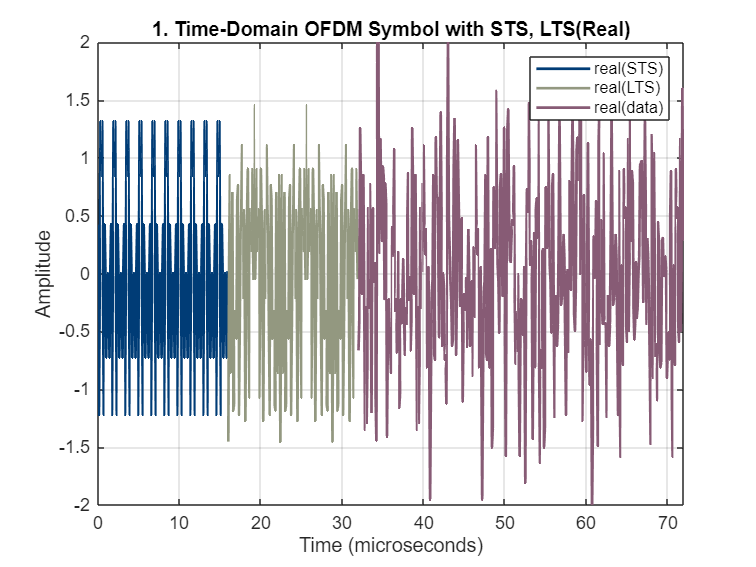

%% (1) Compute and plot magnitude spectrum
STS = STS_generate();
[LTS, single_LTS] = LTS_generate();


% 5- OFDM symbols with STS, LTS;
L_sig_5_head = length(STS) + length(LTS);
L_sig_5 =  L_sig_5_head + 5 * (N_OFDM);
sig_5 = zeros(L_sig_5, 1);

% pre-save data_bits
data_tx = zeros(5*48, 1);

% generate 5 OFDM Symbols
for i = 0:4
    X = ofdm_generate(); % generate single OFDM symbol
    X_shifted = ofdm_shift(X); 
    sig_a = ifft(ifftshift(X_shifted));
    x_cp = ofdm_addCP(sig_a);
    data_tx(48*i+1 : 48*(i+1)) = X(data_idx);
    sig_5(L_sig_5_head + i*(N_OFDM)+1 : L_sig_5_head+(i+1)*(N_OFDM)) = x_cp;
end
sig_5(L_sig_5_head+1:end) = sig_5(L_sig_5_head+1:end)/mean(abs(sig_5(L_sig_5_head+1:end)));

sig_5(1:length(STS)) = STS;
sig_5(length(STS)+1:length(STS)+length(LTS) )= LTS;
bits_tx = qamdemod(data_tx, 4, 'gray', OutputType='bit', UnitAveragePower=true);

time_vector = (0:L_sig_5-1) * ts * 1e6; % Time in microseconds

figure;
p1 = plot(time_vector(1:length(STS)), real(sig_5(1:length(STS))), 'Color', '#003C76', 'LineWidth', 1.5);
hold on;
p2 = plot(time_vector(length(STS)+1:L_sig_5_head), real(sig_5(length(STS)+1:L_sig_5_head) ),'Color', '#939880', 'LineWidth', 1.5);
p3 = plot(time_vector(L_sig_5_head+1:end), real(sig_5(L_sig_5_head+1:end)),'Color', '#875B75', 'LineWidth', 1.5);
xlabel('Time (microseconds)'); ylabel('Amplitude');
axis([0 72 -2 2])
title('1. Time-Domain OFDM Symbol with STS, LTS(Real)');
legend([p1(1), p2(1), p3(1)],'real(STS)', 'real(LTS)','real(data)');
grid on;
hold off;

(2) Transmit the frame generated in (1). Plot the received frame in the time domain with the correct time unit in microseconds. As in (1), please mark the STS, LTS, and data symbols. Please make sure the received signal is of proper signal strength – it should not show signs of clipping, and the signal can be easily distinguishable from the zeros. 

close all;
addpath("./test_code/")

padded_sig_5 = [zeros(100, 1); sig_5; zeros(100, 1)];
% todo: padded must be done in problem (1)

l = length(padded_sig_5);
[radio_Tx,radio_Rx] = USRP_init(l);
buffer = zeros(30*l, 1);
% buffer = zeros(30, l);

% Transmit the frame we generate
% tunderrun = radio_Tx(padded_sig_5);
% [rcvdSignal, ~, toverflow] = step(radio_Rx);
% buffer(1:l) = rcvdSignal;
% buffer(1,:) = rcvdSignal;

% Transmit 15 zero frames 
% (Otherwise there will be no output.) 
% (I not yet know why this bug happens.)
for ii = 1:15
    if ii == 1
        tunderrun = radio_Tx(padded_sig_5);
    else
        tunderrun = radio_Tx(zeros(l, 1));
    end
    % step(radio_Rx);
    [rcvdSignal, ~, toverflow] = step(radio_Rx);
    buffer((1+ii*l-l):(ii*l)) = rcvdSignal;
end

% Keep reception for 15 frames 
for ii = 16 : 30
    [rcvdSignal, ~, toverflow] = step(radio_Rx);
    buffer((1+ii*l-l):(ii*l)) = rcvdSignal;
end 

% To save new data, uncomment this line. 
% Otherwise, keep it commented so that rx_sig.mat won't be modified.
% save rx_sig.mat buffer

release(radio_Tx)
release(radio_Rx)

figure:

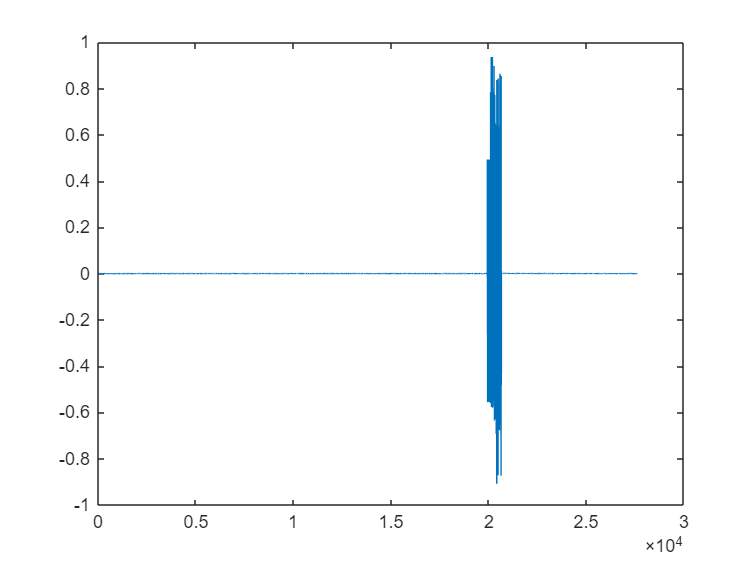

figure;
plot(real(buffer));
ylim([-1,1])

(3) Apply the frame synchronization algorithm you designed in Lab 3 to identify the correct

beginning of the OFDM symbols. Please plot the match filter result.

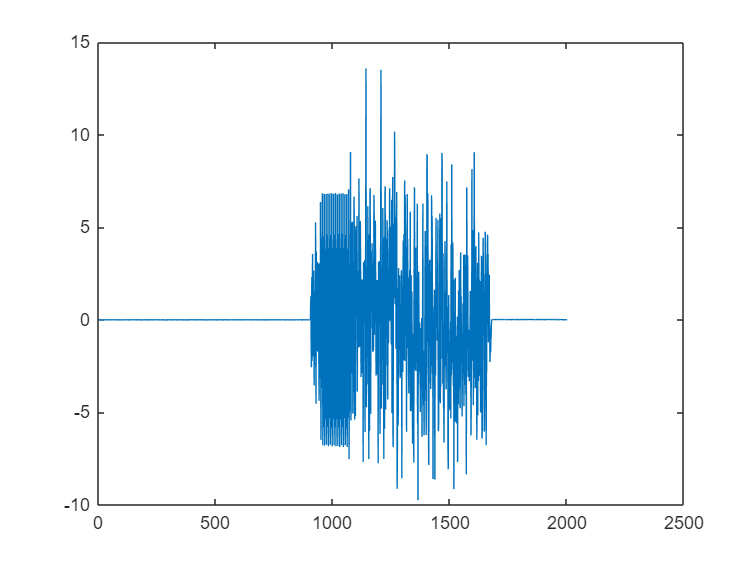

conv_sig_LTS = conv(buffer(1.9e4:2.1e4), single_LTS, "same"); % inden range should be adjusted
plot(real(conv_sig_LTS))

(4) Based on the result, what index marks the beginning of the first long training symbols?

(5) Transform the first long training symbol into the frequency domain and perform channel

estimation. Plot the magnitude and phase of the channel across the subcarriers, from subcarrier

index -26 to 26 (zero-subcarrier in the center).